# enae404 hw07

vai srivastava

## problem 3

addpath("./.") % path to provided code
addpath("../../../code") % path to custom ENAE404 lib

### setup

dep.start = datetime([2022, 08, 01, 12, 00, 00]);
arr.start = datetime([2023, 01, 28, 12, 00, 00]);
dep.end = dep.start+days(500);
arr.end = arr.start+days(500);

epochs.dep = linspace(dep.start, dep.end, 500);
epochs.arr = linspace(arr.start, arr.end, 500);

[DEP, ARR] = meshgrid(epochs.dep, epochs.arr);
TOF = (ARR - DEP);

C3 = zeros(500, 500);
Vinf = zeros(500, 500);

### loop

for h=1:1:500
    dt.dep = epochs.dep(h);
    jd.dep = Provided.ymdhms2jd(dt.dep.Year, dt.dep.Month, dt.dep.Day, dt.dep.Hour, dt.dep.Minute, dt.dep.Second);
    [ Earth.r, Earth.v ] = Provided.findEarth(jd.dep);

    for j=1:1:500
        if (days(TOF(h, j)) >= 45) && (days(TOF(h, j)) <= 500)
            continue
        end
        TOF_sec = seconds(TOF(h, j));

        dt.arr = epochs.arr(j);
        jd.arr = Provided.ymdhms2jd(dt.arr.Year, dt.arr.Month, dt.arr.Day, dt.arr.Hour, dt.arr.Minute, dt.arr.Second);
        [ Mars.r, Mars.v ] = Provided.findMars(jd.arr);

        [ SC.v.dep, SC.v.arr ] = SFD.solve_lambert(Earth.r, Mars.r, TOF_sec, SFD.mu_Sun, false);

        C3(h, j) = norm(SC.v.dep - Earth.v)^2;
        Vinf(h, j) = norm(SC.v.arr - Mars.v);
    end
end

### plot

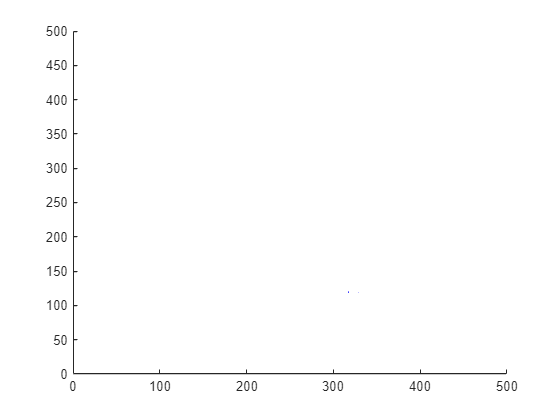

depDays = days(duration(epochs.dep-dep.start));
arrDays = days(duration(epochs.arr-arr.start));
TOFdays = days(TOF);
figure; hold on;
contour(depDays, arrDays, C3, 20, 'b');